For the document network data, the inputs are two matrices. One is the M x N document-term matrix **X**, one is the citation/linkage matrix between M documents in M x M matrix **C**.

## #Initialize this script

clear classes

clear all 
close all
clc

rng(213);
datasets = {'cornell', 'texas', 'washington', 'wisconsin'};

## #Now loading relevent variables/matrices to the workspace

processing_data_id = 1;
load(['../Data/' datasets{processing_data_id} '.mat'], ...
    'C', 'X', 'webpage_ids', 'webpage_classnames');

## #Show the matrix structure

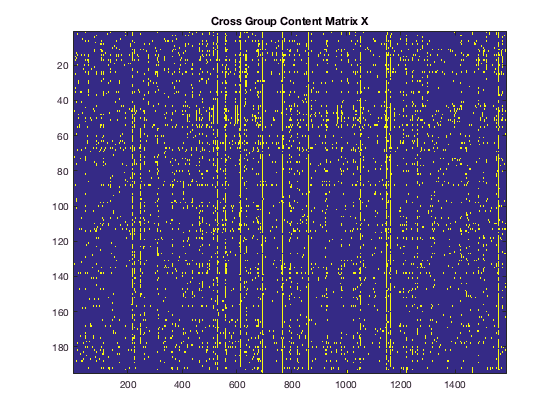

figure
imagesc(X);
title('Cross Group Content Matrix X');

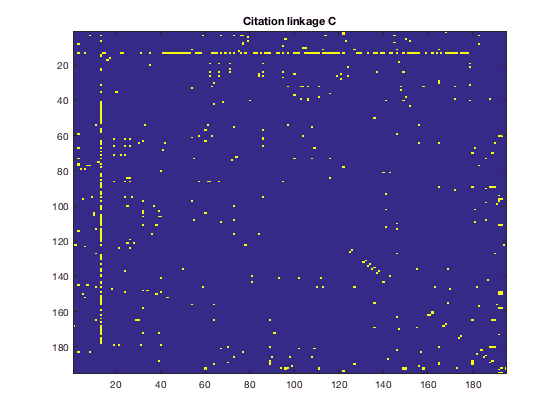


figure
C = C | C.';
imagesc(C);
title('Citation linkage C');